close all;
clear all;
% define inputs and prepare for CBC
w0 = 2*pi;
target = 8;
x_init = [0, 0];
periods = 30;
dt = 1/1000;
[model, input, trial, control] = CL_model_reset(w0,target, x_init, periods, dt);

tv = [0	5.8000;-0.0000	-0.0738;0.0000	-0.6903;-0.0000	-0.0047;0.0000	0.0048;0.0000	0.0002;-0.0000	0.0000]

tv =          0    5.8000
         0   -0.0738
         0   -0.6903
         0   -0.0047
         0    0.0048
         0    0.0002
         0         0


ty2 = [0	3.8401;0.0045	-0.0001;-0.0006	-0.0373;-0.0000	0.0000;0.0000	0.0000;0.0000	0.0000;-0.0000	-0.0000]

ty2 =          0    3.8401
    0.0045   -0.0001
   -0.0006   -0.0373
         0         0
         0         0
         0         0
         0         0


[input_out, trial_out, control_out] = simple_tuner(model, input, trial, control);

Kp = 946.1411

Kd = 432.4014

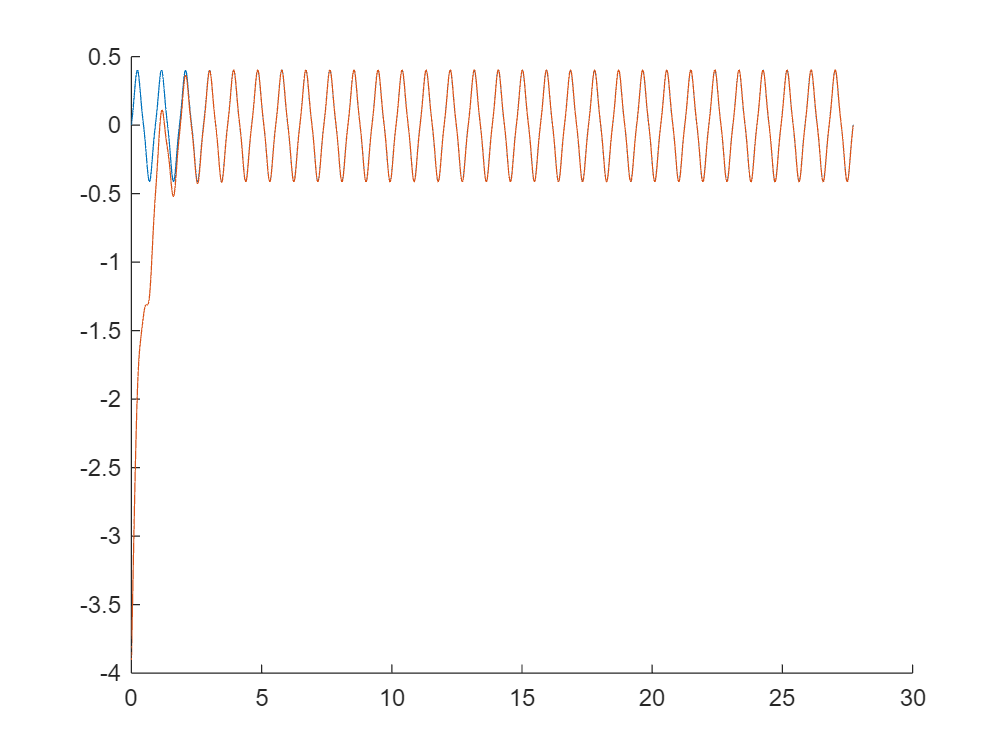

figure;
hold on;
plot(trial_out.t_span, input_out.ref{1}(trial_out.t_span'))
plot(trial_out.t_span, trial_out.X(:, 1))

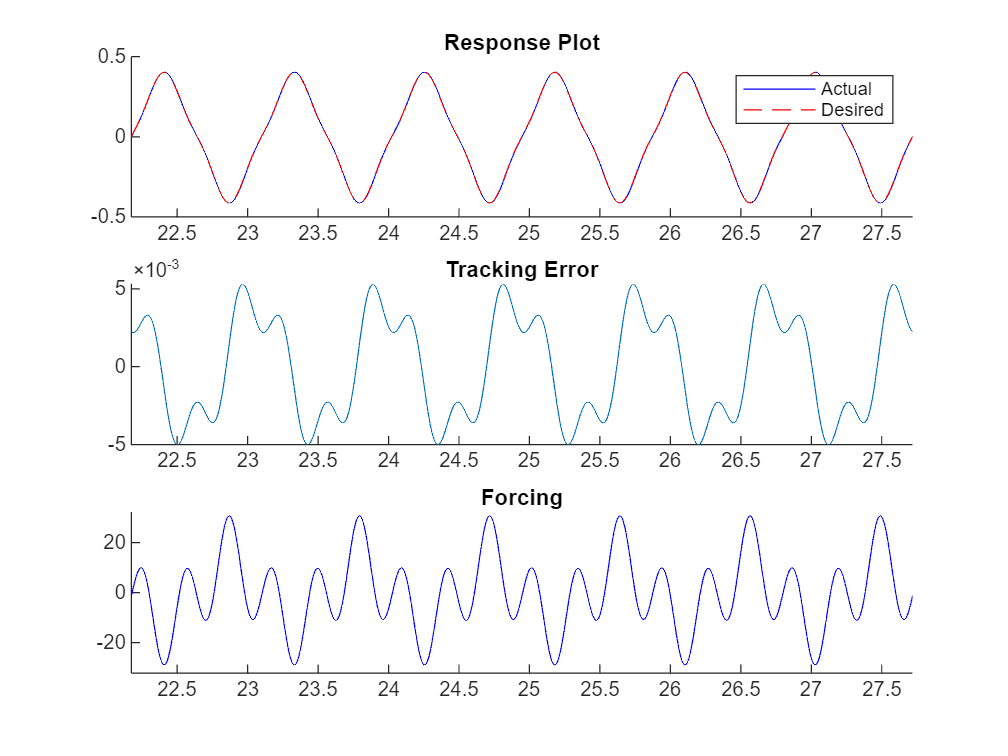

[f] = plot_CL_inner(input_out, trial_out, control);

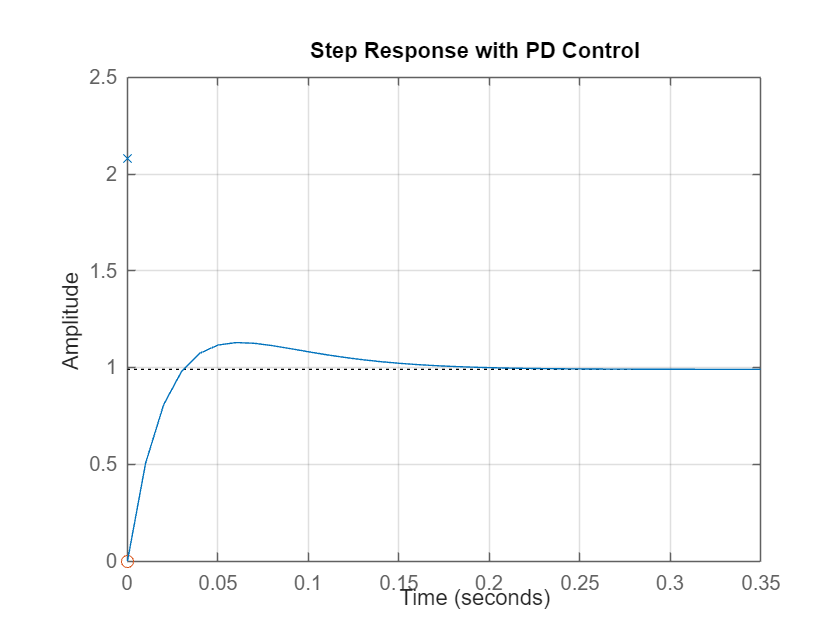


m = model.m; c = model.c; k = model.k;   % System parameters
Ts_desired = (2*pi)/(input.w0*8);          % Desired settling time (sec)
zeta = 1;              % Damping ratio

wn = 4 / (zeta * Ts_desired);
Kp = wn^2 - k;
Kd = 2 * zeta * wn - c;

% Closed-loop system
num = [Kd Kp];
den = [m (c + Kd) (k + Kp)];
sys_cl = tf(num, den);

step(sys_cl); grid on;
title('Step Response with PD Control');

% control.Kp = 3200;
% control.Kd = min(control.Kp, max(10*input.w0/(2*pi), 10));
% control.Kd = Kd;
% control.

control.Kd = Kd;
control.Kp = Kp;
% control.target_vec = ty2
[input_out, trial_out] = closedloop_test(model, input, trial, control);

% model.alpha*target/5
% maxKp = model.m*w0^2-model.k
% maxKd = 2*sqrt(model.m*(model.k+Kp) - model.c)

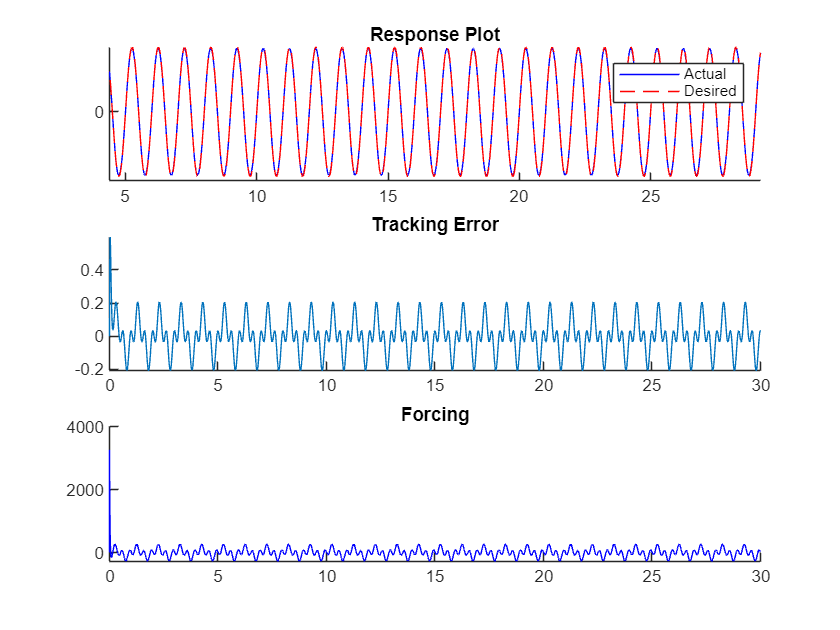

[f] = plot_CL_inner(input_out, trial_out, control);

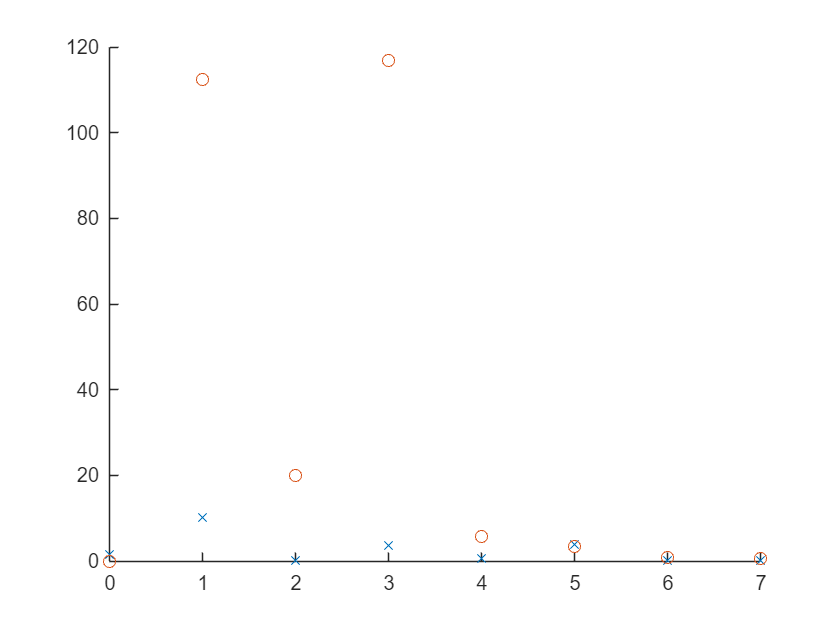

% [t_lin, x_lin] = get_last_n_periods(trial_out.t_span, trial_out.X(:, 1), 10);
[t_lin, x_lin] = get_last_n_periods(trial_out.t_span, input_out.f_history, 10);
[A_vec,B_vec] = get_fft_components(t_lin, x_lin, input_out.w0, control.k_num);
coeffs = (0:7);
figure;
hold on;
scatter(coeffs, abs(A_vec), "x")
scatter(coeffs, abs(B_vec), "o")

[A_vec,B_vec]

ans =    -1.5283         0
  -10.0512 -112.5549
    0.2160   20.0575
    3.5635 -117.0187
    0.6389   -5.7951
    3.9468   -3.4990
   -0.1323   -0.7632
   -0.1047   -0.5876



max_amp = max(trial_out.X(round(8*end/10):end, 1))

max_amp = 7.8392

(max_amp/target - 1)*100

ans = -2.0102

a = linspace(1, 7, 11)
a(9)


figure;
hold on;
grid on;
plot(t_lin, input_out.ref{1}(t_lin))
yline(max(input_out.ref{1}(t_lin)))

input_out